# ** Load fMRI dataset**

clear
% test_imgs = load_image_set('emotionreg');
load('D:\CANlab_Working\CANlab_Note\Emotion Regulation\drive-download-20210518T210113Z-001\AHAB_WithoutRest3_Whole_Beta.mat')  %load fMRI-data

% load('D:\CANlab_Working\BF_Mat\Hansen_2022_PET_tracer_maps.mat') % load PET tracer
[obj, networknames, imagenames]=load_image_set('hansen22') 

Loaded images:
5HT1a_cumi_hc8_beliveau.nii
5HT1a_way_hc36_savli.nii
5HT1b_az_hc36_beliveau.nii
5HT1b_p943_hc65_gallezot.nii
5HT1b_p943_hc22_savli.nii
5HT2a_alt_hc19_savli.nii
5HT2a_cimbi_hc29_beliveau.nii
5HT2a_mdl_hc3_talbot.nii
5HT4_sb20_hc59_beliveau.nii
5HT6_gsk_hc30_radnakrishnan.nii
5HTT_dasb_hc30_savli.nii
5HTT_dasb_hc100_beliveau.nii
A4B2_flubatine_hc30_hillmer.nii
CB1_FMPEPd2_hc22_laurikainen.nii
CB1_omar_hc77_normandin.nii
D1_SCH23390_hc13_kaller.nii
D2_fallypride_hc49_jaworska.nii
D2_flb457_hc37_smith.nii
D2_flb457_hc55_sandiego.nii
D2_raclopride_hc7_alakurtti.nii
DAT_fepe2i_hc6_sasaki.nii
DAT_fpcit_hc174_dukart_spect.nii
GABAa_flumazenil_hc6_dukart.nii
GABAa-bz_flumazenil_hc16_norgaard.nii
H3_cban_hc8_gallezot.nii
M1_lsn_hc24_naganawa.nii
mGluR5_abp_hc22_rosaneto.nii
mGluR5_abp_hc28_dubois.nii
mGluR5_abp_hc73_smart.nii
MU_carfentanil_hc204_kantonen.nii
MU_carfentanil_hc39_turtonen.nii
NAT_MRB_hc10_hesse.nii
NAT_MRB_hc77_ding.nii
VAChT_feobv_hc4_tuominen.nii
VAChT_feobv_hc5_

obj =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'brainmask_canlab.nii'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [36×16 table]
                   dat: [523344×36 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [576094×1 logical]
        removed_images: [36×1 logical]
           image_names: [36×37 char]
              fullpath: [36×109 char]
           files_exist: [36×1 l

networknames = 36×1 table
     target  
    _________

    {'5HT1a'}
    {'5HT1a'}
    {'5HT1b'}
    {'5HT1b'}
    {'5HT1b'}
    {'5HT2a'}
    {'5HT2a'}
    {'5HT2a'}
    {'5HT4' }
    {'5HT6' }
    {'5HTT' }
    {'5HTT' }
    {'a4b2' }
    {'CB1'  }
    {'CB1'  }
    {'D1'   }


imagenames = 36×1 cell array
    {'5HT1a_cumi_hc8_beliveau.nii'          }
    {'5HT1a_way_hc36_savli.nii'             }
    {'5HT1b_az_hc36_beliveau.nii'           }
    {'5HT1b_p943_hc65_gallezot.nii'         }
    {'5HT1b_p943_hc22_savli.nii'            }
    {'5HT2a_alt_hc19_savli.nii'             }
    {'5HT2a_cimbi_hc29_beliveau.nii'        }
    {'5HT2a_mdl_hc3_talbot.nii'             }
    {'5HT4_sb20_hc59_beliveau.nii'          }
    {'5HT6_gsk_hc30_radnakrishnan.nii'      }
    {'5HTT_dasb_hc30_savli.nii'             }
    {'5HTT_dasb_hc100_beliveau.nii'         }
    {'A4B2_flubatine_hc30_hillmer.nii'      }
    {'CB1_FMPEPd2_hc22_laurikainen.nii'     }
    {'CB1_omar_hc77_normandin.nii'          }
    {'D1_SCH23390_hc13_kaller.nii'          }
    {'D2_fallypride_hc49_jaworska.nii'      }
    {'D2_flb457_hc37_smith.nii'             }
    {'D2_flb457_hc55_sandiego.nii'          }
    {'D2_raclopride_hc7_alakurtti.nii'      }
    {'DAT_fepe2i_hc6_sasaki.nii'            }
    {

% obj_masked_zscored_averaged_Resample=resample_space(obj_masked_zscored_averaged, Whole_Neg)  %Resample to same space
obj_masked_zscored_averaged_Resample=resample_space(obj, Whole_Neg)  %Resample to same space

obj_masked_zscored_averaged_Resample =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'brainmask_canlab.nii'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [36×16 table]
                   dat: [242868×36 double]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [242868×1 logical]
        removed_images: [36×1 logical]
           image_names: [36×37 char]
              fullpath: [36×109 char



RegMinusNeg_AHAB = image_math(Whole_Reg, Whole_Neg,'minus' )  %%%Difference betweem Reappraisal and Negative look 

RegMinusNeg_AHAB =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: ' CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [242868×182 single]
           dat_descrip: {'Names of images subtracted in next cells, 1st set minus 2nd'  [182×76 char]  [182×76 char]}
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: []
            

NegMinusNeu_AHAB = image_math(Whole_Neg, Whole_Neu,'minus' )  %%%Negative vs Neutral

NegMinusNeu_AHAB =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: ' CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [242868×182 single]
           dat_descrip: {'Names of images subtracted in next cells, 1st set minus 2nd'  [182×76 char]  [182×76 char]}
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: []
            


load('D:\CANlab_Working\CANlab_Note\Emotion Regulation\drive-download-20210518T210113Z-001\PIP_WithoutRest3_Whole_Beta.mat')

RegMinusNeg_PIP = image_math(Whole_Reg, Whole_Neg,'minus' )  %%%Difference betweem Reappraisal and Negative look 

RegMinusNeg_PIP =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: ' CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [242868×176 single]
           dat_descrip: {'Names of images subtracted in next cells, 1st set minus 2nd'  [176×74 char]  [176×74 char]}
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: []
             

NegMinusNeu_PIP = image_math(Whole_Neg, Whole_Neu,'minus' )  %%%Negative vs Neutral

NegMinusNeu_PIP =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: ' CHANGED SPACE'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [242868×176 single]
           dat_descrip: {'Names of images subtracted in next cells, 1st set minus 2nd'  [176×74 char]  [176×74 char]}
               volInfo: [1×1 struct]
        removed_voxels: 0
        removed_images: 0
           image_names: []
             

% 
% stats1 = image_similarity_plot(NegMinusNeu_AHAB, 'mapset', obj_masked_zscored_averaged_Resample, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged_Resample.metadata_table.target, 'plotstyle', 'polar', 'average');
% title('Look Neg-LookNeu AHAB');
% 
% stats2 = image_similarity_plot(RegMinusNeg_AHAB, 'mapset', obj_masked_zscored_averaged_Resample, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged_Resample.metadata_table.target, 'plotstyle', 'polar', 'average');
% title('Reg Neg-Look Neg AHAB');
% 
% stats3 = image_similarity_plot(NegMinusNeu_PIP, 'mapset', obj_masked_zscored_averaged_Resample, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged_Resample.metadata_table.target, 'plotstyle', 'polar', 'average');
% title('Look Neg-LookNeu PIP');
% 
% stats4 = image_similarity_plot(RegMinusNeg_PIP, 'mapset', obj_masked_zscored_averaged_Resample, 'cosine_similarity', 'bicolor', 'networknames', obj_masked_zscored_averaged_Resample.metadata_table.target, 'plotstyle', 'polar', 'average');
% title('Reg Neg-Look Neg PIP');


# Load identified system


load('D:\CANlab_Working\BF_Mat\Combine_BF_4_6_WithoutRest3_Beta_NewBase_Permute100')

Common_Appraisal=fmri_data(BF_tstat1_fmri);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Reappraisal_Only=fmri_data(BF_tstat2_fmri);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Non_Modificable_Emo_Gen=fmri_data(BF_tstat3_fmri);

Number of unique values in dataset: 2  Bit rate: 1.00 bits


Modificable_Emo_Gen=fmri_data(BF_tstat4_fmri);

Number of unique values in dataset: 2  Bit rate: 1.00 bits



emo_maps = cat(BF_tstat1_fmri, BF_tstat2_fmri, BF_tstat3_fmri, BF_tstat4_fmri);

Recoding, change 0 to 0.00000001

for i=1:100
    Temp=BF_tstat1_fmri.dat(:,i);
    Index=find(Temp==0);
    BF_tstat1_fmri.dat(Index,i)=0.00000001;
    
    Temp=BF_tstat2_fmri.dat(:,i);
    Index=find(Temp==0);
    BF_tstat2_fmri.dat(Index,i)=0.00000001;
    
    Temp=BF_tstat3_fmri.dat(:,i);
    Index=find(Temp==0);
    BF_tstat3_fmri.dat(Index,i)=0.00000001;
    
    Temp=BF_tstat4_fmri.dat(:,i);
    Index=find(Temp==0);
    BF_tstat4_fmri.dat(Index,i)=0.00000001;
end




index1=[1:36];
% index1(34)=[];
index1(26)=[];
index1(13)=[];
index1(35:36)=[13,26];
obj_masked_zscored_averaged_Resample_Reorder=obj_masked_zscored_averaged_Resample;
obj_masked_zscored_averaged_Resample_Reorder.dat=obj_masked_zscored_averaged_Resample_Reorder.dat(:,index1);
obj_masked_zscored_averaged_Resample_Reorder.metadata_table=obj_masked_zscored_averaged_Resample_Reorder.metadata_table(index1,:);
obj_masked_zscored_averaged_Resample_Reorder.image_names=obj_masked_zscored_averaged_Resample_Reorder.image_names(index1,:);
obj_masked_zscored_averaged_Resample_Reorder.fullpath=obj_masked_zscored_averaged_Resample_Reorder.fullpath(index1,:);

Plot radar plot for spatial correlation


Map_Name=obj_masked_zscored_averaged_Resample_Reorder.metadata_table.target

Map_Name = 36×1 cell array
    {'5HT1a'  }
    {'5HT1a'  }
    {'5HT1b'  }
    {'5HT1b'  }
    {'5HT1b'  }
    {'5HT2a'  }
    {'5HT2a'  }
    {'5HT2a'  }
    {'5HT4'   }
    {'5HT6'   }
    {'5HTT'   }
    {'5HTT'   }
    {'CB1'    }
    {'CB1'    }
    {'D1'     }
    {'D2'     }
    {'D2'     }
    {'D2'     }
    {'D2'     }
    {'DAT'    }
    {'DAT'    }
    {'GABAa'  }
    {'GABAabz'}
    {'H3'     }
    {'mGluR5' }
    {'mGluR5' }
    {'mGluR5' }
    {'MOR'    }
    {'MOR'    }
    {'NET'    }


k=1;
for i=1:length(Map_Name)
    Map_Name_Rep{i}=strcat(Map_Name{i},'_',num2str(k));
    if i==length(Map_Name)
        break
    end
    if strcmp(Map_Name{i},Map_Name{i+1})==1
%         Map_Name_Rep{i}=strcat(Map_Name{i},'_','k')
        k=k+1;
    else
        k=1;
    end
end


BF_tstat1_fmri=apply_mask(BF_tstat1_fmri,which ('gray_matter_mask.img'))

BF_tstat1_fmri =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'Volume and in-area mask info from iimg_read_img'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [220211×100 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [242868×1 logical]
        removed_images: [100×1 logical]
           image_names: [100×0 char]
              fullpath: [100×0 

BF_tstat2_fmri=apply_mask(BF_tstat2_fmri,which ('gray_matter_mask.img'))

BF_tstat2_fmri =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'Volume and in-area mask info from iimg_read_img'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [220211×100 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [242868×1 logical]
        removed_images: [100×1 logical]
           image_names: [100×0 char]
              fullpath: [100×0 

BF_tstat3_fmri=apply_mask(BF_tstat3_fmri,which ('gray_matter_mask.img'))

BF_tstat3_fmri =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'Volume and in-area mask info from iimg_read_img'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [220211×100 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [242868×1 logical]
        removed_images: [100×1 logical]
           image_names: [100×0 char]
              fullpath: [100×0 

BF_tstat4_fmri=apply_mask(BF_tstat4_fmri,which ('gray_matter_mask.img'))

BF_tstat4_fmri =   fmri_data with properties:

          source_notes: 'Info about image source here'
                     X: []
                  mask: [1×1 fmri_mask_image]
          mask_descrip: 'Volume and in-area mask info from iimg_read_img'
    images_per_session: []
                     Y: []
               Y_names: []
             Y_descrip: 'Behavioral or outcome data matrix.'
            covariates: []
       covariate_names: {''}
    covariates_descrip: 'Nuisance covariates associated with data'
       history_descrip: 'Cell array of names of methods applied to this data, in order'
       additional_info: [0×0 struct]
        metadata_table: [0×0 table]
                   dat: [220211×100 single]
           dat_descrip: []
               volInfo: [1×1 struct]
        removed_voxels: [242868×1 logical]
        removed_images: [100×1 logical]
           image_names: [100×0 char]
              fullpath: [100×0 

Loaded images:
5HT1a_cumi_hc8_beliveau.nii
5HT1a_way_hc36_savli.nii
5HT1b_az_hc36_beliveau.nii
5HT1b_p943_hc65_gallezot.nii
5HT1b_p943_hc22_savli.nii
5HT2a_alt_hc19_savli.nii
5HT2a_cimbi_hc29_beliveau.nii
5HT2a_mdl_hc3_talbot.nii
5HT4_sb20_hc59_beliveau.nii
5HT6_gsk_hc30_radnakrishnan.nii
5HTT_dasb_hc30_savli.nii
5HTT_dasb_hc100_beliveau.nii
A4B2_flubatine_hc30_hillmer.nii
CB1_FMPEPd2_hc22_laurikainen.nii
CB1_omar_hc77_normandin.nii
D1_SCH23390_hc13_kaller.nii
D2_fallypride_hc49_jaworska.nii
D2_flb457_hc37_smith.nii
D2_flb457_hc55_sandiego.nii
D2_raclopride_hc7_alakurtti.nii
DAT_fepe2i_hc6_sasaki.nii
DAT_fpcit_hc174_dukart_spect.nii
GABAa_flumazenil_hc6_dukart.nii
GABAa-bz_flumazenil_hc16_norgaard.nii
H3_cban_hc8_gallezot.nii
M1_lsn_hc24_naganawa.nii
mGluR5_abp_hc22_rosaneto.nii
mGluR5_abp_hc28_dubois.nii
mGluR5_abp_hc73_smart.nii
MU_carfentanil_hc204_kantonen.nii
MU_carfentanil_hc39_turtonen.nii
NAT_MRB_hc10_hesse.nii
NAT_MRB_hc77_ding.nii
VAChT_feobv_hc4_tuominen.nii
VAChT_feobv_hc5_

ans =   Figure (Neurotransmitter polar plot) with properties:

      Number: 1
        Name: 'Neurotransmitter polar plot'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Number of zero or NaN values within weight mask, by input image:
9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 9708 
Number of zero or NaN values within weight mask, by input image:
9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 9167 916

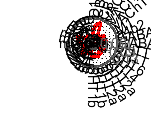

ans = struct with fields:
                     r: [36×100 double]
               descrip: 'Rows are networks, columns are input images.'
          networknames: {1×36 cell}
                     p: [36×1 double]
                   sig: [36×1 double]
                     t: [36×1 double]
                    df: [36×1 double]
         table_spatial: {5×6 cell}
      multcomp_spatial: {630×6 cell}
          line_handles: [1×3 Line]
          fill_handles: [1×3 Patch]
    network_imagenames: [36×37 char]
            inputnames: [100×0 char]
      input_imagenames: [100×0 char]



hansen_neurotransmitter_maps(BF_tstat2_fmri,'doAverage')


stats1 = image_similarity_plot(BF_tstat1_fmri,'corr','mapset', obj_masked_zscored_averaged_Resample_Reorder, 'bicolor', 'networknames', Map_Name_Rep, 'plotstyle', 'polar', 'average','Error_STD');

Number of zero or NaN values within weight mask, by input image:
1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 
Number of zero or NaN values within weight mask, by input image:
7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 764

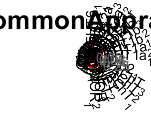

title('CommonAppraisal ');


% stats = image_similarity_plot(BF_tstat1_fmri, 'cosine_similarity', 'mapset', obj_masked_zscored_averaged_Resample_Reorder,'bicolor', 'networknames', Map_Name_Rep, 'plotstyle', 'polar', 'average','treat_zero_as_data');

stats1 = image_similarity_plot(BF_tstat2_fmri,'corr', 'mapset', obj_masked_zscored_averaged_Resample_Reorder, 'bicolor', 'networknames', Map_Name_Rep, 'plotstyle', 'polar', 'average','Error_STD');

Number of zero or NaN values within weight mask, by input image:
1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 
Number of zero or NaN values within weight mask, by input image:
7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 764

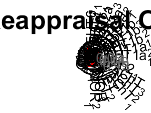

title('Reappraisal Only ');



stats1 = image_similarity_plot(BF_tstat3_fmri, 'corr','mapset', obj_masked_zscored_averaged_Resample_Reorder, 'bicolor', 'networknames', Map_Name_Rep, 'plotstyle', 'polar', 'average','Error_STD');

Number of zero or NaN values within weight mask, by input image:
1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 
Number of zero or NaN values within weight mask, by input image:
7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 764

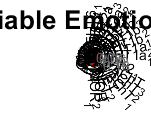

title('Non-Modifiable Emotion generation ');


stats1 = image_similarity_plot(BF_tstat4_fmri, 'corr','mapset', obj_masked_zscored_averaged_Resample_Reorder, 'bicolor', 'networknames', Map_Name_Rep, 'plotstyle', 'polar', 'average','Error_STD');

Number of zero or NaN values within weight mask, by input image:
1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 1230 
Number of zero or NaN values within weight mask, by input image:
7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 7647 764

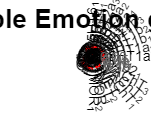

title('Modifiable Emotion generation ');


fname='D:\CANlab_Working\image.nii'

fname = 'D:\CANlab_Working\image.nii'

write(obj_masked_zscored_averaged_Resample, 'fname', fname, 'overwrite');

Writing: 
D:\CANlab_Working\image.nii



%     [hh, hhfill] = tor_polar_plot({R_meanBoot(:,1)}, {[1 0 0]}, obj_masked_zscored_averaged_Resample.metadata_table.target, 'nonneg');
    
% 
% corr(BF_tstat2_fmri.data(:,1),)
% 
% R=canlab_pattern_similarity(obj_masked_zscored_averaged_Resample.dat,BF_tstat2_fmri.dat(:, 2),  'cosine_similarity')'
%   canlab_pattern_similarity(BF_tstat2_fmri.dat(:, 2),obj_masked_zscored_averaged_Resample.dat,  'cosine_similarity')'
%   
%     R=canlab_pattern_similarity(obj_masked_zscored_averaged_Resample.dat,BF_tstat2_fmri.dat(:, :),  'cosine_similarity')';
%     R_meanBoot(1,:)=mean(R,1);
%     R_stdBoot(1,:)=std(R,1);
%     
%     R=canlab_pattern_similarity(obj_masked_zscored_averaged_Resample.dat,BF_tstat1_fmri.dat(:, :),  'cosine_similarity')';
%     R_meanBoot(2,:)=mean(R,1);
%     R_stdBoot(2,:)=std(R,1);
%     
%     R=canlab_pattern_similarity(obj_masked_zscored_averaged_Resample.dat,BF_tstat3_fmri.dat(:, :),  'cosine_similarity')';
%     R_meanBoot(3,:)=mean(R,1);
%     R_stdBoot(3,:)=std(R,1);
%     
%     R=canlab_pattern_similarity(obj_masked_zscored_averaged_Resample.dat,BF_tstat4_fmri.dat(:, :),  'cosine_similarity')';
%     R_meanBoot(4,:)=mean(R,1);
%     R_stdBoot(4,:)=std(R,1);
%     
%         R_meanBoot=R_meanBoot';
% 
%         
%         for i=1:4
%             for j=i+1:4
%                 RR(i,j)=corr(R_meanBoot(i,:)',R_meanBoot(j,:)');
% 
%             end
%         end

% [stats, ntmaps, hh, hhfill, table_group, multcomp_group]=hansen_neurotransmitter_maps(RegMinusNeg_AHAB,'correlation')

### Example images for PET map

5Ht1

figure    
print('5ht1b')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,3:5);
    figure
    montage(Image_ToPlot);

Setting up fmridisplay objects
sagittal montage: 4971 voxels displayed, 133467 not displayed on these slices
axial montage: 28676 voxels displayed, 109762 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices
sagittal montage: 6118 voxels displayed, 164170 not displayed on these slices
axial montage: 36921 voxels displayed, 133367 not displayed on these slices


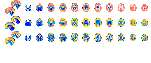


    print('5ht2a')

Setting up fmridisplay objects
sagittal montage: 5929 voxels displayed, 181376 not displayed on these slices
axial montage: 40097 voxels displayed, 147208 not displayed on these slices
sagittal montage: 4795 voxels displayed, 130568 not displayed on these slices
axial montage: 27910 voxels displayed, 107453 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices


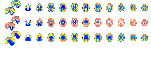

    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,6:8);
    figure
    montage(Image_ToPlot);c

Setting up fmridisplay objects
sagittal montage: 5965 voxels displayed, 143597 not displayed on these slices
axial montage: 33402 voxels displayed, 116160 not displayed on these slices
sagittal montage: 5120 voxels displayed, 135266 not displayed on these slices
axial montage: 28758 voxels displayed, 111628 not displayed on these slices


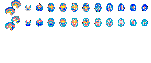


    figure    
    print('5htt')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,11:12);
    montage(Image_ToPlot);

Setting up fmridisplay objects
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices


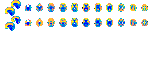

    figure    
    print('CB')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,13:14);
     montage(Image_ToPlot);

Setting up fmridisplay objects
sagittal montage: 6638 voxels displayed, 182270 not displayed on these slices
axial montage: 41101 voxels displayed, 147807 not displayed on these slices
sagittal montage: 8676 voxels displayed, 223745 not displayed on these slices
axial montage: 46692 voxels displayed, 185729 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices


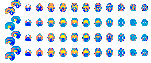

    figure    
    print('D1')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,15:18);
    montage(Image_ToPlot);

Setting up fmridisplay objects
sagittal montage: 8676 voxels displayed, 223745 not displayed on these slices
axial montage: 46692 voxels displayed, 185729 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices
sagittal montage: 7731 voxels displayed, 206046 not displayed on these slices
axial montage: 44051 voxels displayed, 169726 not displayed on these slices


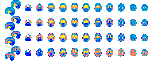


    figure    
    print('D2')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,16:19);
    montage(Image_ToPlot);

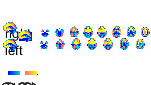

Setting up fmridisplay objects
sagittal montage: 4501 voxels displayed, 227924 not displayed on these slices
sagittal montage: 4437 voxels displayed, 227988 not displayed on these slices
sagittal montage: 4259 voxels displayed, 228166 not displayed on these slices
axial montage: 32861 voxels displayed, 199564 not displayed on these slices
axial montage: 35435 voxels displayed, 196990 not displayed on these slices


    figure    
    print('H3')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,24);
    montage(Image_ToPlot);

Setting up fmridisplay objects
sagittal montage: 6567 voxels displayed, 190508 not displayed on these slices
axial montage: 40183 voxels displayed, 156892 not displayed on these slices
sagittal montage: 8677 voxels displayed, 223748 not displayed on these slices
axial montage: 46692 voxels displayed, 185733 not displayed on these slices


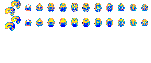


        figure    
    print('H3')
    Image_ToPlot=get_wh_image(obj_masked_zscored_averaged_Resample_Reorder,28:29);
    montage(Image_ToPlot);

## Find most unique map for each system component

for i=1:400
    emomap_topic_correlations(:,i) = canlab_pattern_similarity(obj_masked_zscored_averaged_Resample_Reorder.dat,emo_maps.dat(:,i),'corr');
end

Number of zero or NaN values within weight mask, by input image:
5281 1164 5015  65 1703 1319 5010  65 4973  65 4302 5166  65  65 2298  65  65  65 1182  65 1164 1164 2723  65  65  65  65 1173  65 1615  65  65  65  65  65  65 
Number of zero or NaN values within weight mask, by input image:
4908 1099 4679  52 1628 1265 4632  52 4616  52 4197 4786  52  52 2152  52  52  52 1114  52 1099 1099 2547  52  52  52  52 1115  52 1400  52  52  52  52  52  52 
Number of zero or NaN values within weight mask, by input image:
5657 1380 5567  70 1975 1528 5432  70 5433  70 5075 5587 


Real_emomap_topic_correlations(:,1)=mean(emomap_topic_correlations(:,1:100),2);
Real_emomap_topic_correlations(:,2)=mean(emomap_topic_correlations(:,101:200),2);
Real_emomap_topic_correlations(:,3)=mean(emomap_topic_correlations(:,201:300),2);
Real_emomap_topic_correlations(:,4)=mean(emomap_topic_correlations(:,301:400),2);

Real_emomap_topic_correlations_std(:,1)=std(emomap_topic_correlations(:,1:100),0,2);
Real_emomap_topic_correlations_std(:,2)=std(emomap_topic_correlations(:,101:200),0,2);
Real_emomap_topic_correlations_std(:,3)=std(emomap_topic_correlations(:,201:300),0,2);
Real_emomap_topic_correlations_std(:,4)=std(emomap_topic_correlations(:,301:400),0,2);
Real_emomap_topic_correlations_effectsize(:,1)=mean(emomap_topic_correlations(:,1:100),2)./std(emomap_topic_correlations(:,1:100),0,2);
Real_emomap_topic_correlations_effectsize(:,2)=mean(emomap_topic_correlations(:,101:200),2)./std(emomap_topic_correlations(:,101:200),0,2);
Real_emomap_topic_correlations_effectsize(:,3)=mean(emomap_topic_correlations(:,201:300),2)./std(emomap_topic_correlations(:,201:300),0,2);
Real_emomap_topic_correlations_effectsize(:,4)=mean(emomap_topic_correlations(:,301:400),2)./std(emomap_topic_correlations(:,301:400),0,2);

Real_emomap_topic_correlations_zscores = zscore(Real_emomap_topic_correlations);
for i=1:36
    [B I]=sort(Real_emomap_topic_correlations_zscores(i,:),'descend');
     dis(i,1)=Real_emomap_topic_correlations_zscores(i,I(1))-Real_emomap_topic_correlations_zscores(i,I(2));
    
%     dis(i,1)=emomap_topic_correlations_zscores(i,I(1))-mean(emomap_topic_correlations_zscores(i,I(2:4)),2);
    
    dis(i,2)=I(1);
    dis(i,3)=i;
end

indexReappOnly=find(dis(:,2)==2);

Unique=sortrows(dis,1,'descend')

Unique =           3.72903647188613                         3                        11
          2.41162159019551                         3                        21
           2.3236293545187                         3                        12
          1.88809938548073                         3                        18
          1.75964477665366                         3                        17
          1.47687748494443                         3                        30
          1.35067633202984                         3                        16
          0.96769293573534                         2                        14
         0.918990397777477                         3                        34
         0.821904989265802                         3                        32


for i=1:4
    
    A=find(Unique(:,2)==i);
    id_Uniq(i)=Unique(A(1),3); % find the top 1
end 

for i = 1:4
    % For each emotion map
%     printhdr(names{i})
    
    names{i}=(Map_Name_Rep{id_Uniq(i)})
%         [terms, WrapString] = get_topic_words(topic_obj, id_Uniq(i), true);
end

names = 1×4 cell array
    {'5HT1b_3'}    {'CB1_2'}    {'5HTT_1'}    {'M1_1'}


names = 1×4 cell array
    {'5HT1b_3'}    {'CB1_2'}    {'5HTT_1'}    {'M1_1'}


names = 1×4 cell array
    {'5HT1b_3'}    {'CB1_2'}    {'5HTT_1'}    {'M1_1'}


names = 1×4 cell array
    {'5HT1b_3'}    {'CB1_2'}    {'5HTT_1'}    {'GABAabz_1'}


Loaded images:
5HT1a_cumi_hc8_beliveau.nii
5HT1a_way_hc36_savli.nii
5HT1b_az_hc36_beliveau.nii
5HT1b_p943_hc65_gallezot.nii
5HT1b_p943_hc22_savli.nii
5HT2a_alt_hc19_savli.nii
5HT2a_cimbi_hc29_beliveau.nii
5HT2a_mdl_hc3_talbot.nii
5HT4_sb20_hc59_beliveau.nii
5HT6_gsk_hc30_radnakrishnan.nii
5HTT_dasb_hc30_savli.nii
5HTT_dasb_hc100_beliveau.nii
A4B2_flubatine_hc30_hillmer.nii
CB1_FMPEPd2_hc22_laurikainen.nii
CB1_omar_hc77_normandin.nii
D1_SCH23390_hc13_kaller.nii
D2_fallypride_hc49_jaworska.nii
D2_flb457_hc37_smith.nii
D2_flb457_hc55_sandiego.nii
D2_raclopride_hc7_alakurtti.nii
DAT_fepe2i_hc6_sasaki.nii
DAT_fpcit_hc174_dukart_spect.nii
GABAa_flumazenil_hc6_dukart.nii
GABAa-bz_flumazenil_hc16_norgaard.nii
H3_cban_hc8_gallezot.nii
M1_lsn_hc24_naganawa.nii
mGluR5_abp_hc22_rosaneto.nii
mGluR5_abp_hc28_dubois.nii
mGluR5_abp_hc73_smart.nii
MU_carfentanil_hc204_kantonen.nii
MU_carfentanil_hc39_turtonen.nii
NAT_MRB_hc10_hesse.nii
NAT_MRB_hc77_ding.nii
VAChT_feobv_hc4_tuominen.nii
VAChT_feobv_hc5_

ans =   Figure (Neurotransmitter polar plot) with properties:

      Number: 1
        Name: 'Neurotransmitter polar plot'
       Color: [1 1 1]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


Number of zero or NaN values within weight mask, by input image:
211618 211035 211814 211808 211955 210882 211557 211379 210616 211099 211753 211357 211239 210690 211201 210902 211320 211937 210984 211748 211597 210739 210993 211826 211132 211630 210759 211698 210778 212075 210222 211515 211322 211423 211919 211065 211604 212157 211543 210794 211331 210920 211293 211128 211505 212211 211922 211258 211872 211663 211487 211625 210674 211495 210323 211285 210564 211984 211863 212462 211110 211640 211148 212062 211414 211232 211658 210880 210658 211386 211335 210825 210806 211248 209784 210817 210686 210596 210461 210701 211437 210566 211506 211850 211948 210772 210505 211151 210526 211044 211094 210796 210613 211767 211646 210607 211225 211069 211309 211081 

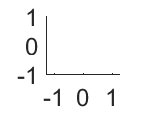

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in tor_polar_plot (line 253)
        set(gca, 'XLim', mylim);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('image_vector/image_similarity_plot', 'C:\Users\KeBo\Documents\GitHub\CanlabCore\CanlabCore\@image_vector\image_similarity_plot.m', 527)" style="font-weight:bold">image_vector/image_similarity_plot<


hansen_neurotransmitter_maps(Reappraisal_Only) 

fname='re.nii'
mask_image=reconstruct_image(obj_masked_zscored_averaged_Resample_Reorder);
write(obj_masked_zscored_averaged_Resample_Reorder, 'fname', fname, 'overwrite');

T=obj_masked_zscored_averaged_Resample_Reorder.metadata_table
filename = 'C:\Users\KeBo\Dropbox (Dartmouth College)\2021_Ke_Bo_reappraisal_Gianaros\Data\NeuroTransmitter\Meta_Neurotrans.xlsx';
writetable(T,filename,'Sheet','MyNewSheet','WriteRowNames',true);